## **Student: Martin Teit Bruun Andersen**

### **Stud-ID: 695245**

### Maskinteknik 3. Semester 2022

#### **Sommer eksamen 2015**

# Opgave A

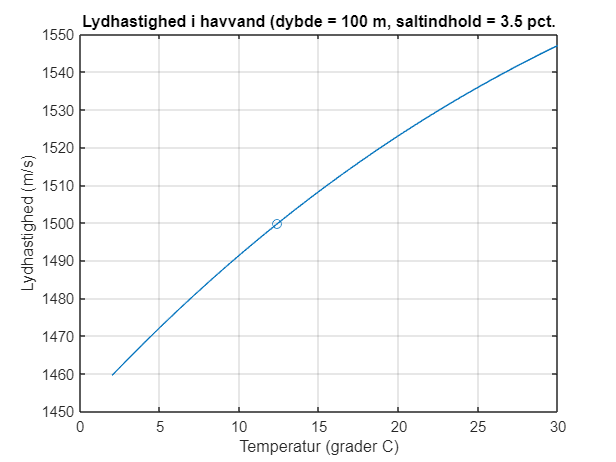

T = linspace(2,30,28);                                     % Temperatur interval fra 2 - 30 grader
c = 0.0002374.*T.^3 - 0.05304.*T.^2 + 4.591.*T + 1450.59;  % Lydhastigheds funktion.

plot(T,c, 'o-','MarkerIndices',11)
grid
xlabel('Temperatur (grader C)')
ylabel('Lydhastighed (m/s)')
title('Lydhastighed i havvand (dybde = 100 m, saltindhold = 3.5 pct.');

# Opgave B

Der er tilbesvarelsen af denne opgave valgt at oprette et punkt på grafen, der markerer det indeks i Linspace, der rammer C(T) = 1500.

I dette tilfælde er det 11.

Så vi får den nøjagtige temperatur til ved at finde værdien bag indeks 11.

Da indekset ikke er et helt runder vi end eller op at afhængeligt af om decimalet er over eller under 0.5

clear
T = linspace(2,30,28);
T_find = T(11) % = 12.3704

T_find = 12.3704

T_1500 = round(T_find)

T_1500 = 12

# Opgave C

clear
f = @(T) 0.0002374*T^3 - 0.05304*T^2 + 4.591*T + 1450.59 - 1500;
Tl = 10;     % Nedre intervalendepunkt (grader C)
Tu = 15;     % Øvre intervalendepunkt (grader C)
es = 0.01;   % Ønsket nøjagtighed af rod
maksit = 20; % Maksimal antal iterationer
it = 0;      % Startværdi for iterationstælleren it
while 1
 Tr = (Tl + Tu)/2;
 ea = abs(Tr-Tl)/Tr*100;
 it = it + 1;
 if f(Tl)*f(Tr) > 0
 Tl = Tr;
 elseif f(Tl)*f(Tr) < 0
 Tu = Tr;
 else
 ea = 0;
 end
 if ea <= es || it >= maksit, break, end
end
T1500 = Tr

T1500 = 12.4548

ea          % Den estimerede nøjatighed af rod.

ea = 0.0098

it

it = 12

# Opgave D

Resultatet for opgaven er:

Root = 12.4545

ea = 1.0758e-09

Iter = 4

clear
func = @(T) 0.0002374*T^3 - 0.05304*T^2 + 4.591*T + 1450.59 - 1500;
dfunc = @(T) 0.0007122*T^2 - 0.10608*T + 4.591;

xr = 15;                          % Start værdi
es = 0.0001;                      % Den approksimative fejl
maxit = 100;                      % Maksimalt antal iterationer
iter = 0; 

% Tomme array til tabellen:
arr = [];                         
arr1 = [];
arr2 = [];

while (1) 
 xrold = xr; 
 xr = xr - func(xr)/dfunc(xr);
 arr(end + 1) = xr;
 iter = iter + 1;
 arr1(end + 1) = iter;
 if xr ~= 0;
 ea = abs((xr - xrold)/xr) * 100;
 arr2(end +1) = ea;
 end 
 if ea <= es || iter >= maxit, break, end 
end

varNames = {'Root', 'Iter', 'ea'};
rootTable = table(arr', arr1', arr2','VariableNames',varNames)

rootTable = 4×3 table
     Root     Iter        ea    
    ______    ____    __________

    12.366     1          21.296
    12.454     2         0.70649
    12.455     3      0.00081303
    12.455     4      1.0758e-09


% Dobbelt check:
root = xr                        

root = 12.4545

ea                                

ea = 1.0758e-09

iter          

iter = 4

# Opgave E

clear
func = @(T) 0.0002374*T^3 - 0.05304*T^2 + 4.591*T + 1450.59 - 1500;
output = optimset('Display', 'iter');
x = fzero(func,12,output) % Virker både med interval som gætte værdi.

 
Search for an interval around 12 containing a sign change:
 Func-count    a          f(a)             b          f(b)        Procedure
    1              12      -1.54553            12      -1.54553   initial interval
    3         11.6606      -2.71166       12.3394      -0.38966   search
    5           11.52       -3.1977         12.48     0.0861286   search
 
Search for a zero in the interval [11.52, 12.48]:
 Func-count    x          f(x)             Procedure
    5           12.48     0.0861286        initial
    6         12.4548    0.00104474        interpolation
    7         12.4545  -6.68228e-09        interpolation
    8         12.4545   2.27374e-13        interpolation
    9         12.4545             0        interpolation
 
Zero found in the interval [11.52, 12.48]


x = 12.4545

# Opgave F

p = [0.0002374 -0.05304 4.591 -49.41];
x = roots(p)

x = 1.0e+02 *

   1.0548 + 0.7473i
   1.0548 - 0.7473i
   0.1245 + 0.0000i


#### **Eksamen Forår 2016**

# Opgave A

**(Jeg har ladet Matlab aflæse rødderne som heltal i stedet for at danne et array og indsætte dem. Håber dette er okay; på trods af at det ikke følger opgave beskrivelsen?)**

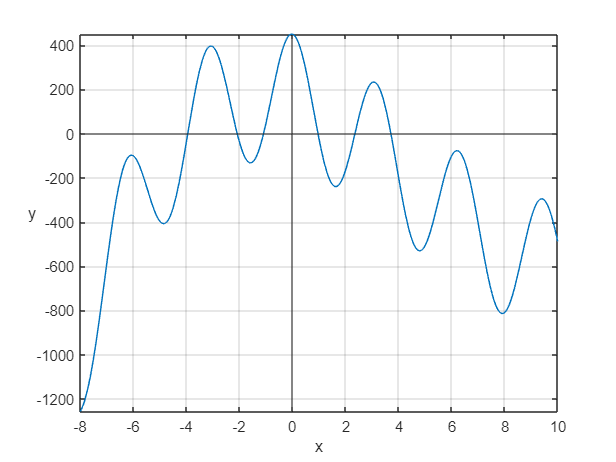

clear
f = @(x) 300*cos(2*x)+x.^3 - 14 * x.^2 - 36 * x + 150;

fplot(f,[-8 10])
xline(0)
yline(0)
grid
xlabel('x')
ylabel('y',Rotation=0);

arr = [-8 -3 -1 0 1 2 4];
arrTabel = [];
for i=1:length(arr)
    g = fzero(f,arr(i));
    arrTabel(end + 1) = g;
end

varName = {'Rødderne som heltal'};
Tab = table(arrTabel, 'VariableNames',varName)

Tab = table
    Rødderne som heltal
    ___________________

        1×7 double     


# Opgave B

Resultatet af endenstående giver god mening i reference til spg. A.

Ses der på Tabellen, som jeg har dannet, der beskriver de nøjagtige x-koordinater for x = 0;

så kan vi fra denne opgave se, at der skal være en krydsning på x-aksen mellem -4 & -3 som vores første krydsning.

Dette stemmer overens med tabellen skabt i A.

Går man punkterne igennem, så vil man se, at der vil være en sammenhæng.

clear
f = @(x) 300*cos(2*x)+x^3-14*x^2-36*x+150;
for x = -100:100
 if f(x)*f(x+1) < 0
    disp([x,x+1])
 end
end

    -4    -3

    -3    -2

    -2    -1

     0     1

     2     3

     3     4

    15    16



# Opgave C

Forsøg nummer 1 er at foretrække, da vi har et højere (bredere) start-interval.

Forsøg 1:

clear
f = @(x) 300*cos(2*x)+x^3-14*x^2-36*x+150;
Tl = 1;      % Nedre intervalendepunkt (grader C)
Tu = 3;      % Øvre intervalendepunkt (grader C)
es = 0.01;   % Ønsket nøjagtighed af rod
maksit = 20; % Maksimal antal iterationer
it = 0;      % Startværdi for iterationstælleren it
while 1
 Tr = (Tl + Tu)/2;
 ea = abs(Tr-Tl)/Tr*100;
 it = it + 1;
 if f(Tl)*f(Tr) > 0
 Tl = Tr;
 elseif f(Tl)*f(Tr) < 0
 Tu = Tr;
 else
 ea = 0;
 end
 if ea <= es || it >= maksit, break, end
end
Root = Tr

Root = 2.3551

it = 14

Forsøg 2:

clear
f = @(x) 300*cos(2*x)+x^3-14*x^2-36*x+150;
Tl = 1.75;     % Nedre intervalendepunkt (grader C)
Tu = 2.25;     % Øvre intervalendepunkt (grader C)
es = 0.01;     % Ønsket nøjagtighed af rod
maksit = 20;   % Maksimal antal iterationer
it = 0;        % Startværdi for iterationstælleren it
while 1
 Tr = (Tl + Tu)/2;
 ea = abs(Tr-Tl)/Tr*100;
 it = it + 1;
 if f(Tl)*f(Tr) > 0
 Tl = Tr;
 elseif f(Tl)*f(Tr) < 0
 Tu = Tr;
 else
 ea = 0;
 end
 if ea <= es || it >= maksit, break, end
end
Root = Tr

Root = 2.2499

it = 12